# 给图形标注添加说明

## Apparence

*title(title)*

*给图形添加说明*

*xlabel(xlabel)*

*在横轴添加说明*

*ylabel(ylabel)*

*在纵轴添加说明*

*text(x, y, text)*

*在pos给出说明*

*legend()*

*给出图例*

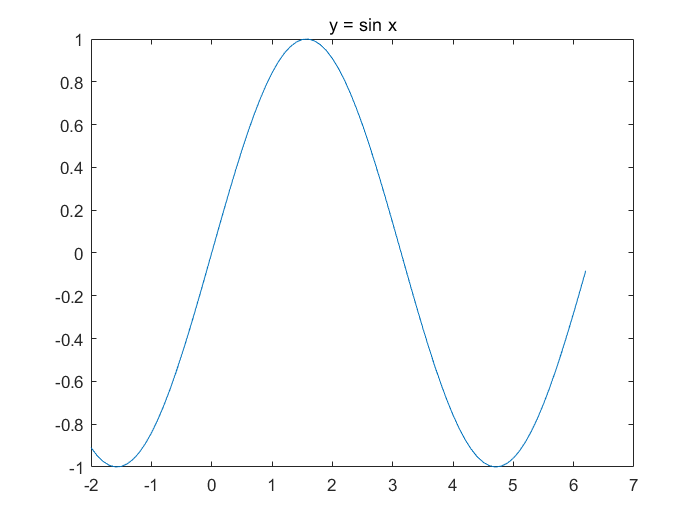

x=-2:0.1:2*pi;
y=sin(x);
plot(x, y)
title('y = sin x')

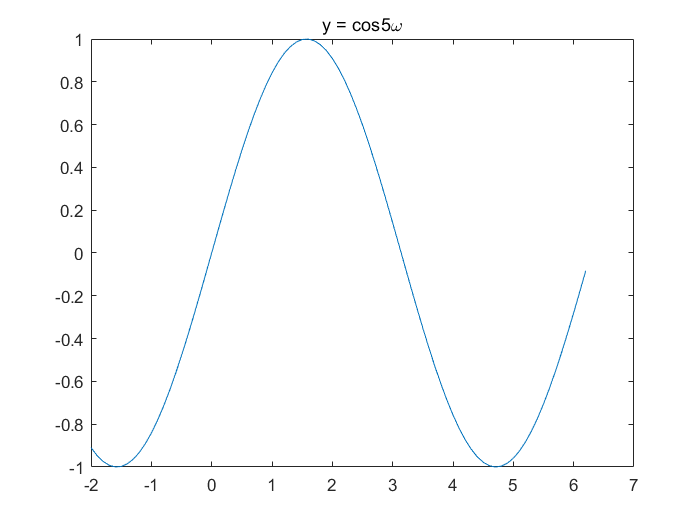

omega = -2:0.1:2*pi;
y = sin(omega*5);
title('y = cos5{\omega}')

% LaTex formation

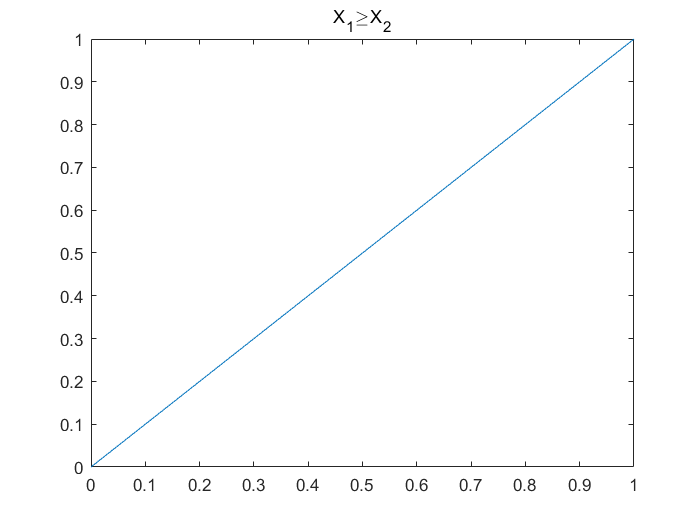

plot(0:1, 0:1)
title('X_{1}{\geq}X_{2}')

Use **\bf** *\it*

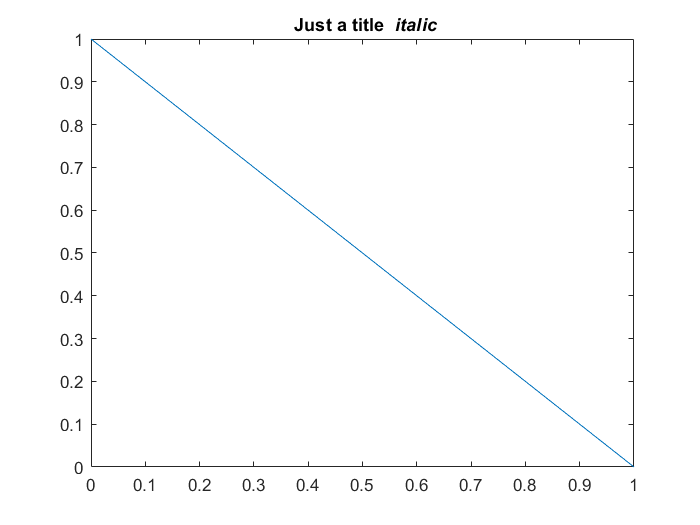

plot(0:1, flip(0:1))
title('\bf Just a title \it italic')

## Advance:

title('title', attr_name, attr_value)

to set certain attribute.

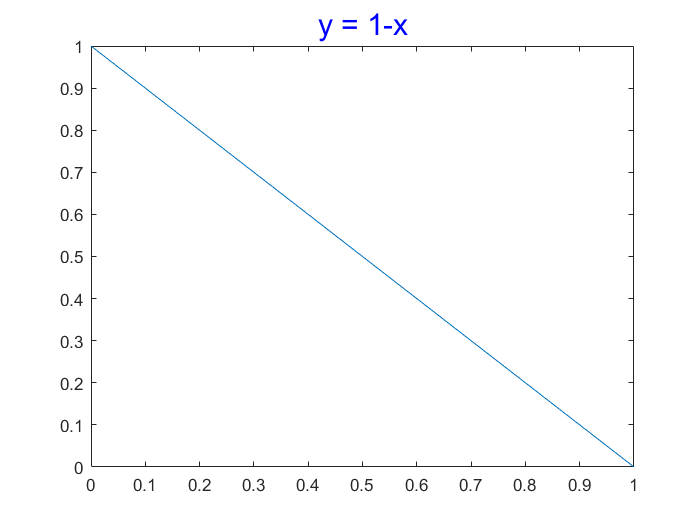

plot(0:1, flip(0:1))
title('y = 1-x', 'Color', 'b', 'FontSize', 18)

% Color is blue and FontSize=18

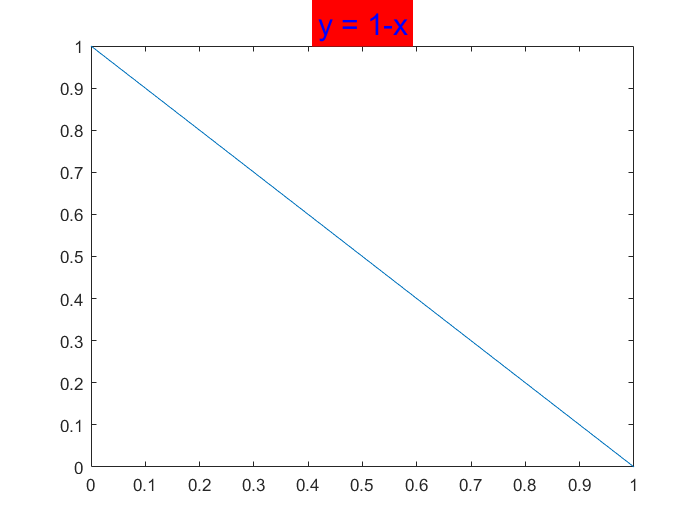

t =   Text (y = 1-x) - 属性:

                 String: 'y = 1-x'
               FontSize: 18
             FontWeight: 'normal'
               FontName: 'Helvetica'
                  Color: [0 0 1]
    HorizontalAlignment: 'center'
               Position: [0.5000 1.0064 1.4211e-14]
                  Units: 'data'

  显示 所有属性


plot(0:1, flip(0:1))
t= title('y = 1-x', 'Color', 'b', 'FontSize', 18);
% Color is blue and FontSize=18
t.BackgroundColor = 'red';
t.Editing = 'on'

## xlabel & ylabel

we can create labels using func xlabel() and ylabel()

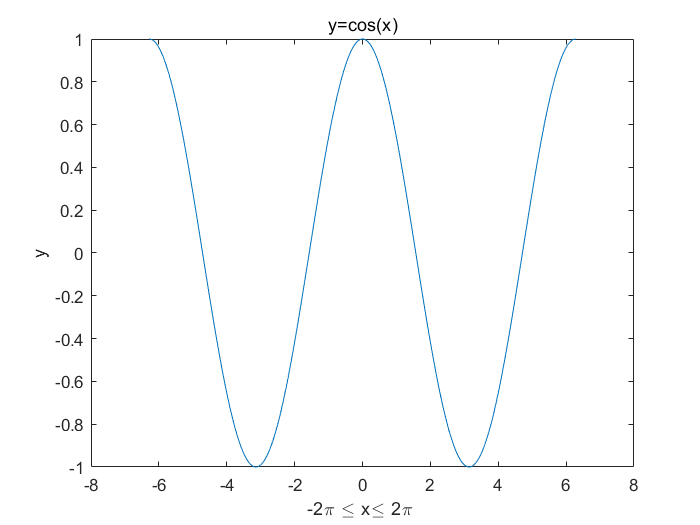

x=(-2:0.01:2)*pi;
y=cos(x);
plot(x, y);
title('y=cos(x)');
xlabel('-2\pi \leq x\leq 2\pi ');
ylabel('y');

## text & gtext

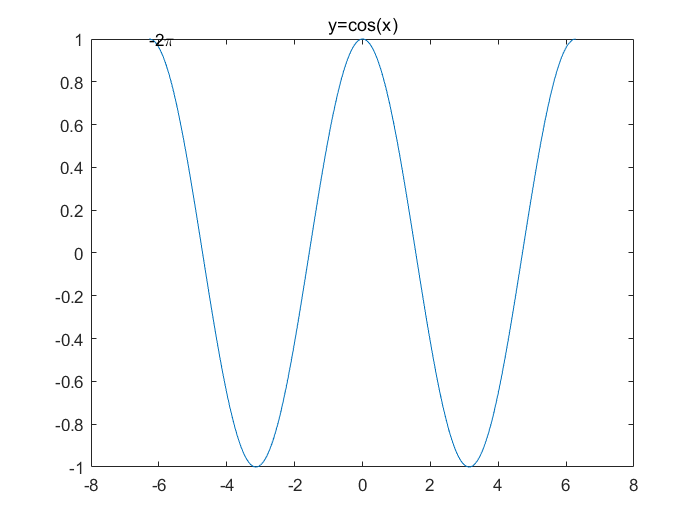

x=(-2:0.01:2)*pi;
y=cos(x);
plot(x, y);
title('y=cos(x)');
text(-2*pi, 1, '-2{\pi}');

## legend

Syntax:

legend(legend1, legend2, ...)

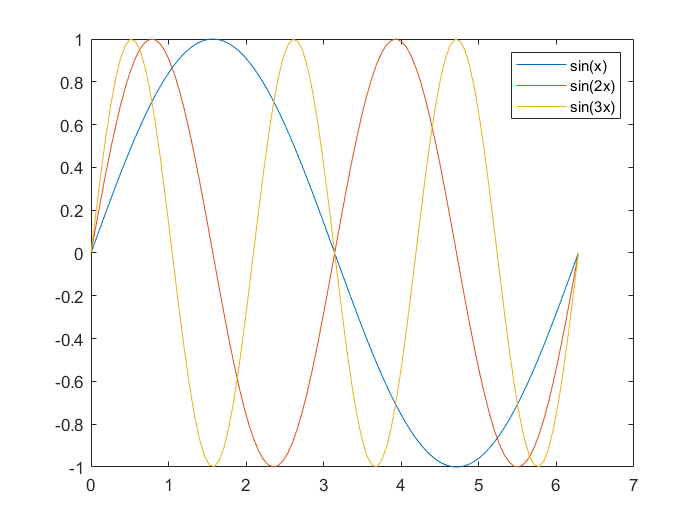

x=linspace(0, 2*pi, 100);
plot(x, [sin(x); sin(2*x); sin(3*x)]);
legend('sin(x)', 'sin(2x)', 'sin(3x)');